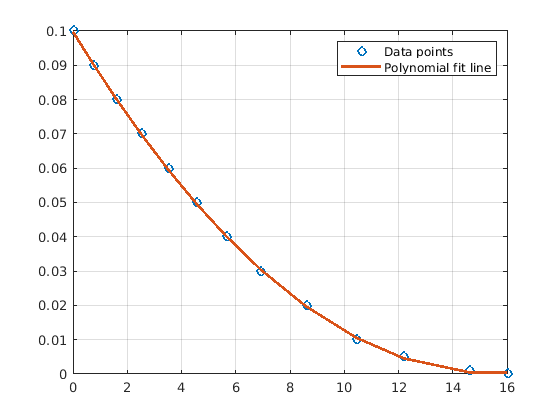

clear all; close all; clc;

% Data
% Data from video
t = [0 0.744 1.602 2.525 3.514 4.537 5.658 6.911 8.593 10.437 12.2 14.6 16];
h = [0.1 0.09 0.08 0.07 0.06 0.05 0.04 0.03 0.02 0.01 0.005 0.001 0];

% Arguments: t list, h list, polynomial degree
p = polyfit(t,h, 2);

% Make a new list with points on the polynomial line based on the time
% values
polynomial_line = polyval(p, t);

% Plot result
% Plot points
plot(t,h, 'o', 'LineWidth', 2)
hold on
% Plot polynomial line
plot(t,polynomial_line, 'LineWidth', 2)
legend("Data points", "Polynomial fit line")
grid